clear all;
MUDACdatatest=readtable('Test-Truncated-Restated.xlsx');

MUDACdatatraining=readtable('Training-Restated.xlsx');




%match id

% I chose 'stable' because this maintains the same order as the training
% data set. If we decide against this later, we can just remove that
% argument

[uniquematchID,unique2training,training2unique]=unique(MUDACdatatraining.MatchID18Char,'stable');


## Response variables by program type

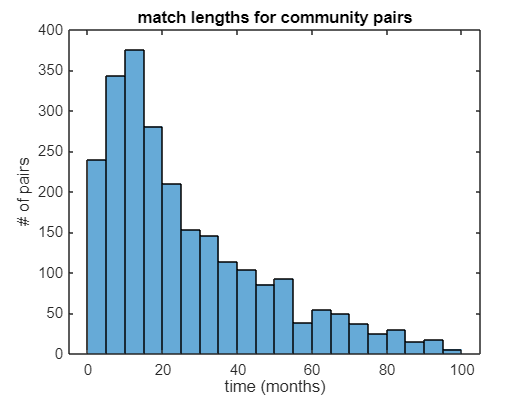


programTypes = MUDACdatatraining.ProgramType(unique2training);
matchLengths = MUDACdatatraining.MatchLength(unique2training);

simplifiedData1 = table(uniquematchID,programTypes,matchLengths);

% 1 == community, 0 == site-based/site
programTypesBinary = ismember(programTypes,"Community");

lengthComm = simplifiedData1.matchLengths(programTypesBinary ==1);
lengthSite = simplifiedData1.matchLengths(programTypesBinary ==0);

histogramComm = histogram(lengthComm);
title('match lengths for community pairs')
xlabel('time (months)')
ylabel('# of pairs')

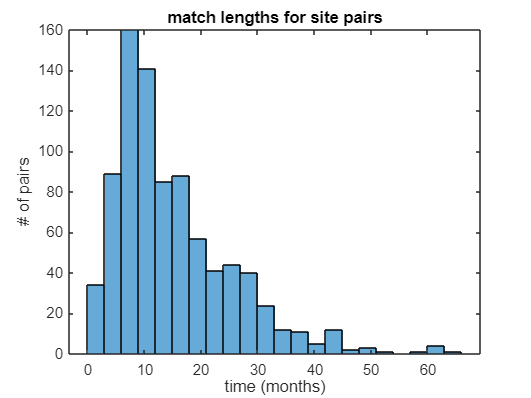


histogramSite = histogram(lengthSite);
title('match lengths for site pairs')
xlabel('time (months)')
ylabel('# of pairs')